# Constrained Zonotope

In CORA, constrained zonotopes are instantiated by 

% cZ = conZonotope(c,G,A,b);

where `c` is the zonotope center, `G` is the generator matrix, `A` is the constraint matrix, and `b` is the constraint offset. 

Example:

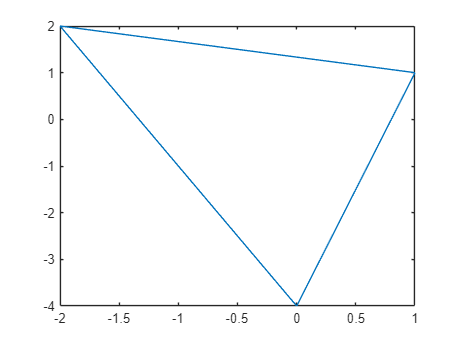

% initialize constrained zonotope
c = [0;0];
G = [1 0 1; 1 2 -1];
A = [-2 1 1];
b = 2;
cZ = conZonotope(c,G,A,b);

% plot constrained zonotope
plot(cZ);

For more information, type

help conZonotope

  conZonotope - object constructor for constrained zonotopes [1]
 
  Description:
     This class represents constrained zonotope objects defined as
     {c + G * beta | ||beta||_Inf <= 1, A * beta = b}.
 
  Syntax:
     obj = conZonotope(c,G)
     obj = conZonotope(c,G,A,b)
     obj = conZonotope(Z)
     obj = conZonotope(Z,A,b)
 
  Inputs:
     c - center vector of the zonotope
     G - generator matrix of the zonotope
     Z - matrix containing zonotope center and generators Z = [c,G]
     A - constraint matrix A*beta = b
     b - constraint vector A*beta = b
 
  Outputs:
     obj - generated conZonotope object
 
  Example: 
     c = [0;0];
     G = [3 0 1; 0 2 1];
     A = [1 0 1]; b = 1;
     cZ = conZonotope(c,G,A,b);
     plot(cZ);
 
  References:
     [1] Scott, Joseph K., et al. "Constrained zonotopes:
            A new tool for set-based estimation and fault 